00.18

clear
clc
close all

mot.k = 5.2;
mot.T = 0.03;
a = 0.17;
tau = 0.015;
k = 40;
res = 2000;
umax = 10;
bit = 10;
Ts = 0.001;
wc = 2 * pi * 150;
dl = 1 / sqrt(2);
deg2rad = pi / 180;
rad2deg = 180 / pi;
pulse2deg = 360 / res;
rpm2rads = 2 * pi / 60;
rads2rpm = 60 / (2 * pi);
degs2rpm = 60/360;
rpm2degs = 360/60;

z = tf('z', Ts);
s = (1 - z^-1) / Ts;
C = minreal(k * (1 + tau * s) / (s * (1 + a * tau * s)), 1e-6);
[numC, denC] = tfdata(C, 'v');
H = minreal(wc^2 * s / (s^2 + 2 * dl * wc * s + wc^2), 1e-6);
[numH, denH] = tfdata(H, 'v');

r.A = 250; % [rpm]
r.t = 0.1; % [s]

open("ex3_sim1m.slx")

set_param("ex3_sim1m", "SolverType", "Variable-Step", "Solver", "ode45", ...
    "MaxStep", "0.0001", "StopTime", "0.5")
sim("ex3_sim1m")

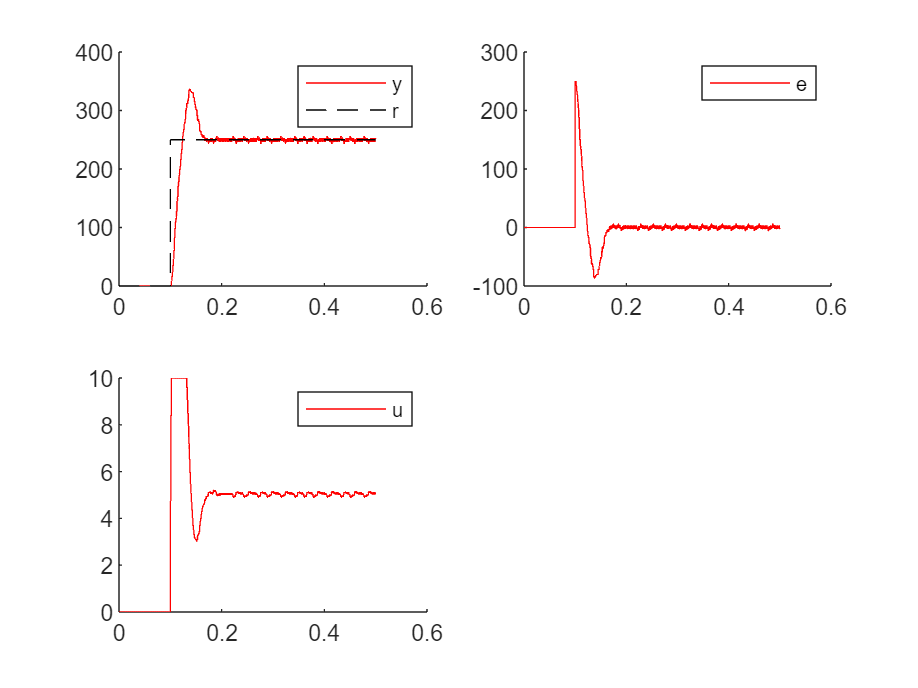

close all
figure(1)
subplot(2, 2, 1)
hold on
plot(sim1_res.time, sim1_res.signals(1).values, "r")
plot(sim1_res.time, sim1_res.signals(2).values, "k--")
legend("y", "r")

subplot(2, 2, 2)
hold on
plot(sim1_res.time, sim1_res.signals(3).values, "r")
legend("e")

subplot(2, 2, 3)
hold on
plot(sim1_res.time, sim1_res.signals(4).values, "r")
legend("u")

p2 = 1 / (a * tau);
k1 = k;
k2 = k * (1 - a) / a;
C2 = k2 / (s + p2);
[numC2, denC2] = tfdata(C2, 'v');
Kawu = 200;

open_system("ex3_sim2m.slx")

set_param("ex3_sim2m", "SolverType", "Variable-Step", "Solver", "ode45", ...
    "MaxStep", "0.0001", "StopTime", "0.5")
sim("ex3_sim2m")

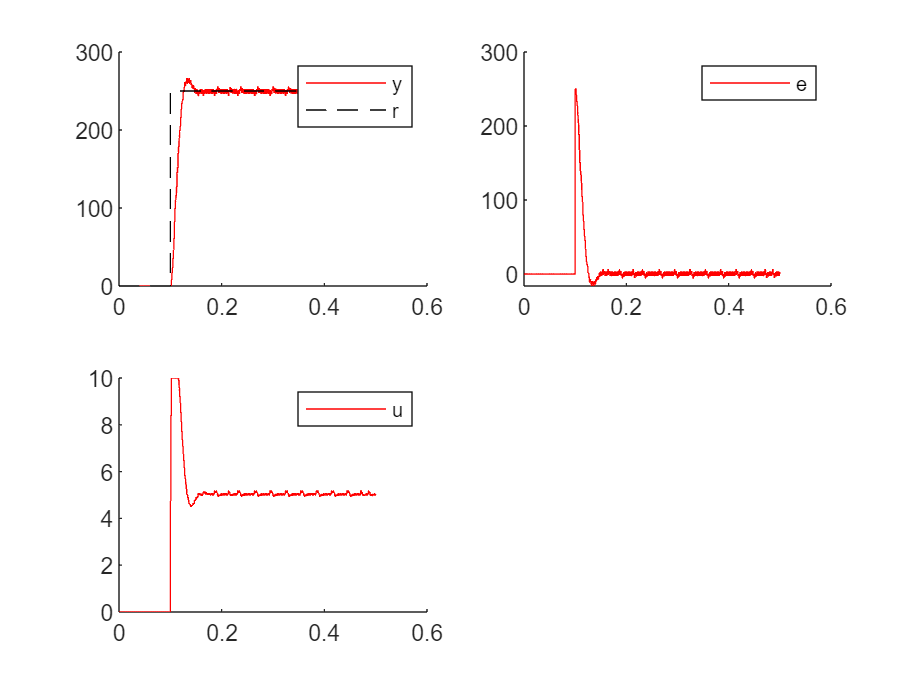

close all
figure(2)
subplot(2, 2, 1)
hold on
plot(sim2_res.time, sim2_res.signals(1).values, "r")
plot(sim2_res.time, sim2_res.signals(2).values, "k--")
legend("y", "r")

subplot(2, 2, 2)
hold on
plot(sim2_res.time, sim2_res.signals(3).values, "r")
legend("e")

subplot(2, 2, 3)
hold on
plot(sim2_res.time, sim2_res.signals(4).values, "r")
legend("u")

00.53